dirList = {'\\atlas\Chem\ARGO_PROCESSING\DATA\CAL';
    '\\atlas\Chem\ARGO_PROCESSING\DATA\FloatVIZ_SNAPSHOTS\SOCCOM_GO-BGC_snapshot_23Jun2024\SOCCOM_GO-BGC_LoResQC_CANYONB_23Jun2024\SOCCOM_GO-BGC_LoResQC_CANYONB_23Jun2024';
    '\\atlas\Chem\ARGO_PROCESSING\DATA\FloatVIZ_SNAPSHOTS\SOCCOM_GO-BGC_snapshot_20Dec2023\SOCCOM_GO-BGC_LoResQC_CANYONB_20Dec2023\SOCCOM_GO-BGC_LoResQC_CANYONB_20Dec2023';
    '\\atlas\Chem\ARGO_PROCESSING\DATA\FloatVIZ_SNAPSHOTS\SOCCOM_GO-BGC_snapshot_28Aug2023\SOCCOM_GO-BGC_LoResQC_CANYONB_28Aug2023\SOCCOM_GO-BGC_LoResQC_CANYONB_28Aug2023';
    '\\atlas\Chem\ARGO_PROCESSING\DATA\FloatVIZ_SNAPSHOTS\SOCCOM_GO-BGC_snapshot_26Apr2023\SOCCOM_GO-BGC_LoResQC_CANYON_26Apr2023\SOCCOM_GO-BGC_LoResQC_CANYON_26Apr2023';
    '\\atlas\Chem\ARGO_PROCESSING\DATA\FloatVIZ_SNAPSHOTS\SOCCOM_snapshot_21Dec2022\SOCCOM_LoResQC_CANYON_21Dec2022\SOCCOM_LoResQC_CANYON_21Dec2022';
    '\\atlas\Chem\ARGO_PROCESSING\DATA\FloatVIZ_SNAPSHOTS\SOCCOM_snapshot_19May2022\SOCCOM_LoResQC_CANYON_19May2022\SOCCOM_LoResQC_CANYON_19May2022';
    '\\atlas\Chem\ARGO_PROCESSING\DATA\FloatVIZ_SNAPSHOTS\SOCCOM_snapshot_21Dec2021\SOCCOM_LoResQC_CANYON_21Dec2021\SOCCOM_LoResQC_CANYON_21Dec2021';
    '\\atlas\Chem\ARGO_PROCESSING\DATA\FloatVIZ_SNAPSHOTS\SOCCOM_snapshot_01Sep2021\SOCCOM_LoResQC_CANYON_01Sep2021\SOCCOM_LoResQC_CANYON_01Sep2021';
    '\\atlas\Chem\ARGO_PROCESSING\DATA\FloatVIZ_SNAPSHOTS\SOCCOM_snapshot_05May2021\SOCCOM_LoResQC_CANYON_05May2021'};

dateList = [datetime("now");
    datetime(2024,6,23);
    datetime(2023,12,20);
    datetime(2023,8,28);
    datetime(2023,4,26);
    datetime(2022,12,21);
    datetime(2022,5,19);
    datetime(2021,12,21);
    datetime(2021,9,1);
    datetime(2021,5,5)];

%Create an empty array with columns DATE GOBGC SOCCOM OTHER and a row for each snapshot
profCounts = NaN(length(dirList),3);

for i = 1:length(dirList)
    load([dirList{i} '\MBARI_float_list.mat'])
    iCYC = find(strcmp('max cycle proc',d.hdr) == 1);
    iPROG = find(strcmp('Program',d.hdr) == 1);
    
    gobgcIDX = contains(d.list(:,iPROG),'GO-BGC');
    soccomIDX = contains(d.list(:,iPROG),'SOCCOM');
    otherIDX = ~contains(d.list(:,iPROG),'GO-BGC')&~contains(d.list(:,iPROG),'SOCCOM');
    
    gobgc_profs = sum(cell2mat(d.list(gobgcIDX,iCYC)),'omitmissing');
    soccom_profs = sum(cell2mat(d.list(soccomIDX,iCYC)),'omitmissing');
    other_profs = sum(cell2mat(d.list(otherIDX,iCYC)),'omitmissing');

    profCounts(i,1) = gobgc_profs;
    profCounts(i,2) = soccom_profs;
    profCounts(i,3) = other_profs;
end

fig = figure;


bar(dateList,profCounts)

title("Profile counts by program since May 2021");
ylabel("Profiles");
xlabel("Date");
legend({'GO-BGC', 'SOCCOM', 'OTHER'},'Location','bestoutside')

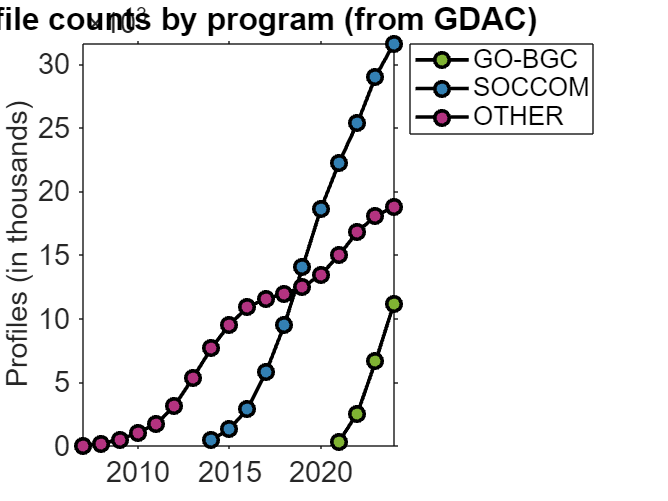

%LOAD FLOATLIST
floatList = readtable("\\atlas\Chem\ARGO_PROCESSING\DATA\CAL\MBARI_float_list.txt");

%LOAD SPROF INDEX
argoDat = readtable(getenv('USERPROFILE')+"\documents\argo_synthetic-profile_index.txt");

%Split the SPROF INDEX filenames by '/' and isolate the 7-digit WMO_ID
fileSplit = split(argoDat.file,'/');

%Create a seperate column in the data table for WMOs that uses the second column of the split string
argoDat.WMO=str2double(fileSplit(:,2));

%Create indices of WMOs from GOBGC, SOCCOM, and OTHER programs from the floatlist
gobgcIDX = contains(floatList.Program,'GO-BGC');
soccomIDX = contains(floatList.Program,'SOCCOM');
otherIDX = ~contains(floatList.Program,'GO-BGC')&~contains(floatList.Program,'SOCCOM');

%Call the WMOs from the program indices
GOBGCfloats = floatList.WMO(gobgcIDX);
SOCCOMfloats = floatList.WMO(soccomIDX);
OTHERfloats = floatList.WMO(otherIDX);

%Retrieve all profiles from the synthetic-profile_index for each respective program using the above indices:

%GO-BGC
isGOBGCfloat = ismember(argoDat.WMO,GOBGCfloats); %Tests whether each row in argoDat contains the WMO from GOBGC floats
GOBGCprofs = argoDat(isGOBGCfloat,:); %Subset argoDat using the above logical array as the index

%SOCCOM: does the same as above but using SOCCOM floats
isSOCCOMfloat = ismember(argoDat.WMO,SOCCOMfloats);
SOCCOMprofs = argoDat(isSOCCOMfloat,:);

%OTHER: does the same as above but using floats from non-GOBGC and non-SOCCOM floats
isOTHERfloat = ismember(argoDat.WMO,OTHERfloats);
OTHERprofs = argoDat(isOTHERfloat,:);

%GOBGC:
%Convert dates to strings for each subset (faster to segment the conversion than to run on the entire SPROF index)
GOBGCprofs.date = num2str(GOBGCprofs.date);
GOBGCprofs.datetime = datetime(GOBGCprofs.date, 'InputFormat', 'yyyyMMddHHmmss');

%Group the profiles by year
[GOBGCprofs_byYr, GOBGC_YR] = groupcounts(year(GOBGCprofs.datetime(ismember(GOBGCprofs.WMO,GOBGCfloats))));

%Find the cumulative sum of floats for every year
GOBGCprofs_byYr = cumsum(GOBGCprofs_byYr);

%SOCCOM:
SOCCOMprofs.date = num2str(SOCCOMprofs.date);
SOCCOMprofs.datetime = datetime(SOCCOMprofs.date, 'InputFormat', 'yyyyMMddHHmmss');
[SOCCOMprofs_byYr, SOCCOM_YR] = groupcounts(year(SOCCOMprofs.datetime(ismember(SOCCOMprofs.WMO,SOCCOMfloats))));
SOCCOMprofs_byYr = cumsum(SOCCOMprofs_byYr);

%OTHER:
OTHERprofs.date = num2str(OTHERprofs.date);
OTHERprofs.datetime = datetime(OTHERprofs.date, 'InputFormat', 'yyyyMMddHHmmss');
[OTHERprofs_byYr, OTHER_YR] = groupcounts(year(OTHERprofs.datetime(ismember(OTHERprofs.WMO,OTHERfloats))));
OTHERprofs_byYr = cumsum(OTHERprofs_byYr);

%PLOTTING
%----------------------------------------------------------------------------------------%
fig = figure;

hold on;

%GOBGC
plot(GOBGC_YR,GOBGCprofs_byYr,'-o','MarkerSize',8,'LineWidth',2,'Color','k', ...
            'MarkerEdgeColor','k','MarkerFaceColor',[0.5 0.7 0.2])

%SOCCOM
plot(SOCCOM_YR,SOCCOMprofs_byYr,'-o','MarkerSize',8,'LineWidth',2,'Color','k', ...
            'MarkerEdgeColor','k','MarkerFaceColor',[0.2 0.5 0.7])

%OTHER
plot(OTHER_YR,OTHERprofs_byYr,'-o','MarkerSize',8,'LineWidth',2,'Color','k', ...
            'MarkerEdgeColor','k','MarkerFaceColor',[0.7 0.2 0.5])

ax = gca;
ax.Box = 'on';
ax.TickDir = 'out';
ax.FontSize = 16;
ax.YAxis.Exponent = 3;

title("Profile counts by program (from GDAC)");
ylabel("Profiles (in thousands)",'FontSize', 16);
legend({'GO-BGC', 'SOCCOM', 'OTHER'},'Location','bestoutside');

%List of MBARI floats that are on our floatlist but not on the SPROF index
floatList(~ismember(floatList.WMO,unique(argoDat.WMO)),:)